# Sensitivity Analysis with MATLAB for  Student Competition Scores

In the current blog post, we will explore the concept of sensitivity analysis and its significance in engineering design. Our attention will be on the student competition score function, especially competitions focused on model aircraft design, i.e. AIAA Design Build Fly, SAE AeroDesign, etc, as a case study to investigate how distinctive design variables affect the mission score. To demonstrate this, we will use the scoring function, from the [AIAA Design Build Fly Competition 2021 Rule Book](https://www.aiaa.org/docs/default-source/uploadedfiles/aiaadbf/resources/dbf-rules-2021-final-v01-3.pdf?sfvrsn=6b92352a_0), with MATLAB plotting approach By the end of the blog, you will better understand how to make informed design choices to optimize the competition score. Enjoy!

## What is Sensitivity Analysis?

Sensitivity Analysis (SA) is a technique used to measure the impact of uncertainties in input variables on output variables in a model. SA aims to determine which input variables impact the output most and identify the range of values in which the model is most sensitive. This information helps to design a robust model with reduced uncertainties. 

SA is practiced in a range of fields, including but not limited to finance, engineering, and economics. Specifically, in the field of engineering design, it helps engineers optimize their designs and to improve the quality, reliability, and performance of the system. Although several SA methods exist, such as Univariate SA, Multivariate SA, Local SA, and Global SA, the first two are widely used in engineering design.  Model aircraft design competitions, such as the [AIAA DBF](https://www.aiaa.org/dbf/example-dbf-feature) and [SAE Aero Design](https://www.sae.org/attend/student-events/sae-aero-design-east/), are no exception. SA is used here specifically to evaluate score sensitivity. It helps teams identify the most sensitive design variables and optimize their vehicle designs to maximize their score.

## Competition Problem Statement

The objective of the AIAA DBF 2021 contest was to carry out a towed sensor. The mission involved transportation of sensors in shipping containers, and surveillance by deploying, operating, and recovering a towed sensor.

Teams were required to complete 4 missions, consisting of 1 ground mission and 3 flight missions. The main challenge was to find a trade-off between the design variables to maximize the total mission score. The mission score for each mission was as follows:

Mission 1 (No payload flight)                                                                             $\textrm{M1}=1\;$                                                                                   on successful flight only 

Mission 2 Delivery Flight (Sensors in a shipping container(s) as Payload)      $\textrm{M2}=1+\frac{N\_\;\left(\frac{\textrm{#Sensors}}{\textrm{Time}\;\textrm{for}\;3\;\textrm{laps}}\right)}{\textrm{Max}\_\;\left(\frac{\textrm{#Sensors}}{\textrm{Time}\;\textrm{for}\;3\;\textrm{laps}}\right)}$                                           max mission window of 5 min

Mission 3 Sensor Flight (Sensor deploying and recovering)                             $\textrm{M3}=\;2+\frac{N\_\;\left(\left.\textrm{#laps}\;*\;\textrm{sensor}\;\textrm{length}\;*\textrm{sensor}\;\textrm{weight}\right)\right)}{\textrm{Max}\_\;\left(\left.\textrm{#laps}\;*\;\textrm{sensor}\;\textrm{length}\;*\textrm{sensor}\;\textrm{weight}\right)\right)}$      max mission window of 10 min. 

Ground Mission (Loading of payload)                                                               $\textrm{GM}=\frac{\textrm{Fastest}\;\textrm{Time}}{\textrm{Time}}$

Total Mission Score                                                                                           $\textrm{TMS}\;=\textrm{M1}+\textrm{M2}+\textrm{M3}+\textrm{GM}$

All missions need to be completed as per the flight course shown in Figure 1.

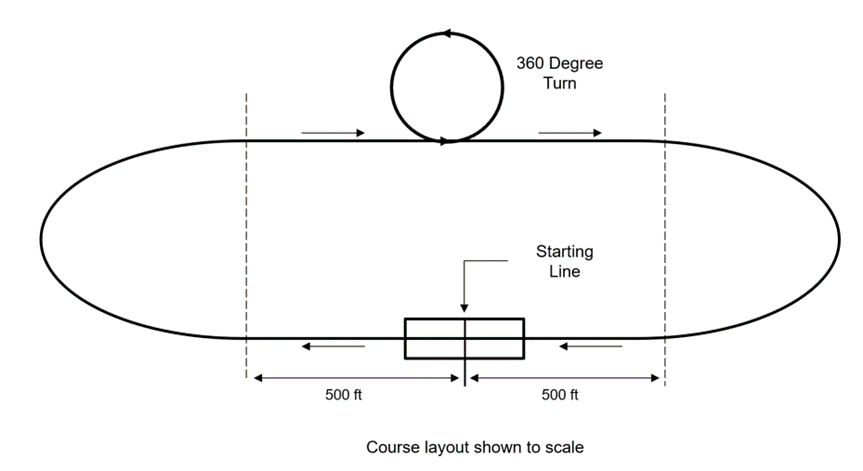

*Figure **1: Flight Course*

## Score Sensitivity Analysis with Plotting Approach in MATLAB

### 1.1    Total Mission Score Analysis

The total mission score depends on multiple missions with different objectives. From the total mission score, it can be inferred that:

- Mission 1 does not play a significant role, as it only requires a successful flight.

- The ground mission involves loading and unloading the payload in the minimum time, and thus, mostly depends on the crew's skills. 

- Prioritizing Mission 2's cruise velocity to minimize flight time drives the design towards a smaller, faster aircraft. 

- Prioritizing increased payload in Missions 2 and 3 drives the design towards a heavier, slower aircraft.

Points 3 and 4 direct the model design to conflicting requirements. To identify the priority sequence of missions, SA can be used. The scoring function has limited input variables, so Univariate SA can provide reliable results. Univariate SA is used to understand the impact of uncertainties in individual input variables while assuming other input variables constant. 

As all the mission scores of each team are relative to the best-performing team, the following parameters can be assumed based on the performance of the best teams in previous competitions.

% Defining parameters for the best-performing team
bestTeam.Sensors = 20;                          % in numbers (Number of sensors to be used by the best-performing team)
bestTeam.Laps = 20;                             % in numbers (Number of laps to be completed in mission 3 by the best-performing team)
bestTeam.FlightTime = 150;                      % in seconds (total flight time for 3 laps in Mission 2 by the best-performing team) 
bestTeam.SensorWeight = 1.4;                    % in lbs (weight of each sensor to be carried by the best-performing team)
bestTeam.SensorLength = 30;                     % in inch (weight of each sensor to be carried by the best-performing team)
bestTeam.GM = 30;                               % in seconds(time taken to complete ground mission)

% Copyright 2023 The MathWorks, Inc.

To define mission score functions, and to calculate the maximum mission score, individual teams’ parameters can be considered equivalent to the best-performing team. 

% Defining parameters for the team
team = bestTeam;

As per the [AIAA DBF 2021 Competition Rule Book](https://www.aiaa.org/docs/default-source/uploadedfiles/aiaadbf/resources/dbf-rules-2021-final-v01-3.pdf?sfvrsn=6b92352a_0), mission scores can be formulated as follows:

% Mission score formulation as per formulas mentioned in the Competition Problem Statement section
score.Max.M1 = 1;						                                                                                                        % Mission 1 Score
score.Max.M2 = 1 + (team.Sensors/team.FlightTime)/(bestTeam.Sensors/bestTeam.FlightTime);								                        % Mission 2 Score
score.Max.M3 = 2 + (team.Laps * team.SensorLength * team.SensorWeight) / (bestTeam.Laps * bestTeam.SensorLength * bestTeam.SensorWeight);		% Mission 3 Score
score.Max.GM = bestTeam.GM/team.GM;			                                                                                                    % Ground Mission Score
score.Max.Total = score.Max.M1 + score.Max.M2 + score.Max.M3 + score.Max.GM;                                                                    % total maximum mission score

For Mission 1, the score is awarded only on a successful flight. Also, it does not affect any other parameters. Hence, Mission 1 can be eliminated for sensitivity analysis. 

To perform the sensitivity analysis, each score is varied in a change. Here, a change vector is needed which varies parameters from -50% to +50%.

% Change vector to perform SA
change = -0.5:0.1:0.5;

The effect of the sensitivity of each mission score on the total score is studied as follows:

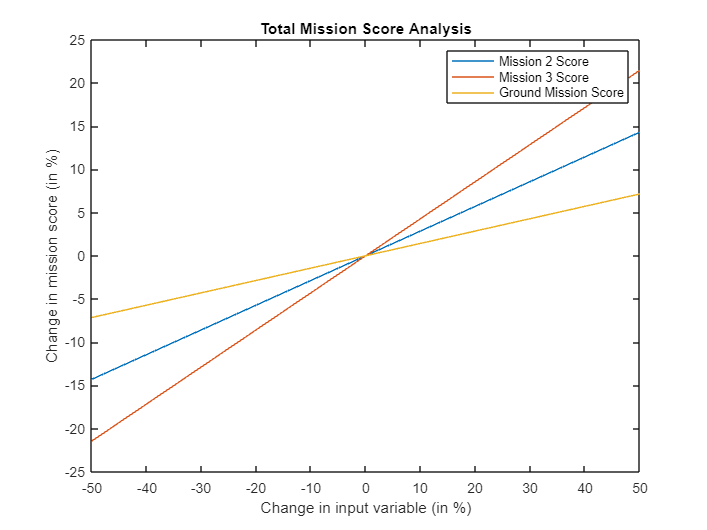

% Impact of Mission 2 score on Total Score
score.Total.M2 = score.Max.M1 + score.Max.M2*(1+change) + score.Max.M3 + score.Max.GM;								% Mission 2 score vector
score.Total.Change.M2 = (score.Total.M2 - score.Max.Total)/score.Max.Total*100;									% Mission 2 score change vector
% Impact of Mission 3 score on Total Score
score.Total.M3 = score.Max.M1 + score.Max.M2 + score.Max.M3*(1+change) + score.Max.GM;								% Mission 3 score vector
score.Total.Change.M3 = (score.Total.M3 - score.Max.Total)/score.Max.Total*100;									 % Mission 3 score change vector

% Impact of Ground Mission score on Total Score
score.Total.GM = score.Max.M1 + score.Max.M2 + score.Max.M3 + score.Max.GM*(1+change);								% Ground Mission score vector
score.Total.Change.GM = (score.Total.GM - score.Max.Total)/score.Max.Total*100;									% Ground Mission score change vector

% Plotting sensitivity analysis plot
plots.Y1.Name = {'Mission 2 Score', 'Mission 3 Score', 'Ground Mission Score'};
plots.Y1.Value = [score.Total.Change.M2',  score.Total.Change.M3', score.Total.Change.GM'];

figure()
plot(change*100,plots.Y1.Value)
legend(plots.Y1.Name)
xlabel('Change in input variable (in %)')
ylabel('Change in mission score (in %)')
title('Total Mission Score Analysis')

In the above plot, the higher the slope, the more sensitive the mission. Hence, the following inferences can be made from the above plot:

- As expected, Ground Mission is less sensitive and depends on crew skills. Hence, it can be ignored. 

- Mission 3 is the most sensitive followed by Mission 2.

- Mission 2 has two variables: the number of sensors and the total time for three laps. 

- Mission 3 has a total of three design variables: sensor length, sensor weight, and number of laps. 

- To explore the most sensitive design variable, in both Mission 2 and Mission 3, Univariate SA can be performed on both mission scores individually.

### 1.2    Mission-2 Score Analysis

For Mission-2, the number of sensors and flight time are two important parameters to be evaluated as follows:

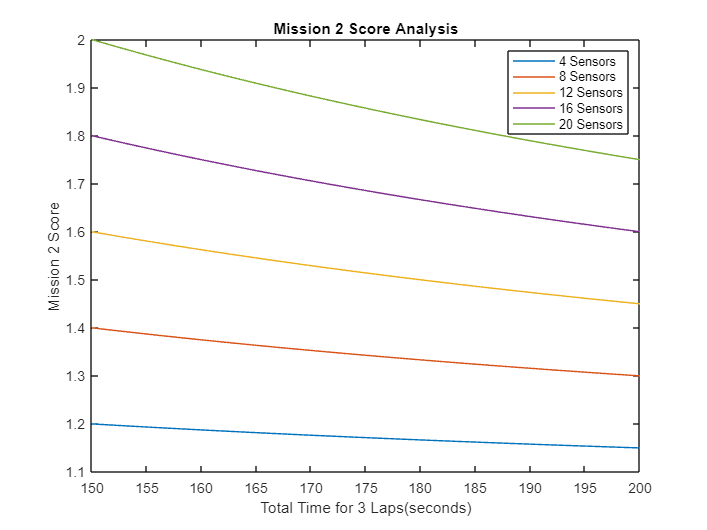

% Defining flight time vector for three laps for the team
team.Array.FlightTime = [linspace(bestTeam.FlightTime,200,50)]';

% Univariate SA for Mission 2 score with flight time and number of sensor
% variation
team.Array.Sensor = [4:4:20].*ones(50,5);
score.Array.M2 = 1 + (team.Array.Sensor ./ team.Array.FlightTime)/(bestTeam.Sensors/ bestTeam.FlightTime);
plots.Y2.Value = score.Array.M2;
plots.Y2.Name = {'4 Sensors','8 Sensors','12 Sensors','16 Sensors','20 Sensors'};

% Plotting sensitivity analysis plot
figure()
plot(team.Array.FlightTime,plots.Y2.Value)
legend(plots.Y2.Name)
xlabel('Total Time for 3 Laps(seconds)')
ylabel('Mission 2 Score')
title('Mission 2 Score Analysis')

In the above plot, the slope of the curves are negative and increases with more sensors. Hence, flight time becomes more sensitive on  increasing number of sensors compared to a lower number of sensors. Hence:

- Number of sensors are more sensitive to Mission-2 score than flight time.

- As the curve slope is negative hence flight time impacts mission scores in the opposite way. Hence a faster aircraft will score more.

- A lighter and faster aircraft will score less compared to a heavy aircraft.

- A heavy aircraft will score more on getting faster.

### 1.3    Mission-3 Score Analysis

For Mission 3, sensor length, sensor weight, and the number of laps are important parameters to be evaluated. From the previous section, it is inferred that a heavy and faster aircraft will score more. Considering the number of sensors constant as per the Mission 2 requirements, the effect of all three variables on each other can be studied as follows:

#### 1.3.1    Number of Laps and Sensor Weight Correlation

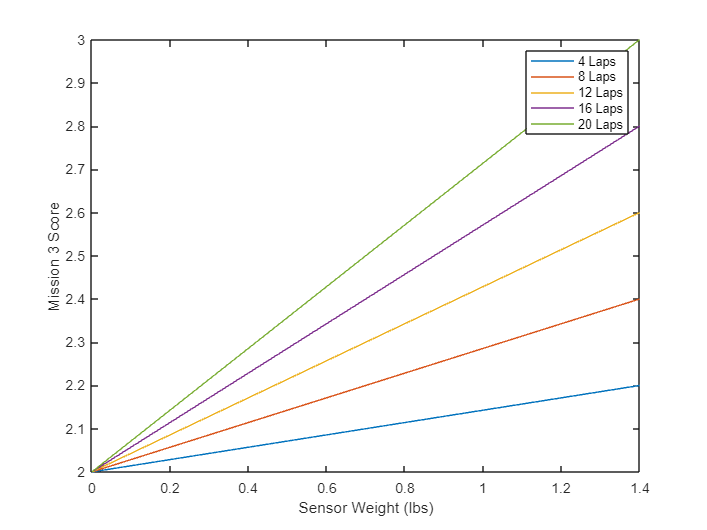

% Defining sensor weight vector for the team
team.Array.SensorWeight = [linspace(0,bestTeam.SensorWeight, 50)]';

% Univariate SA for Mission 3 score with the number of laps and sensor weight variation
team.Array.Laps = [4:4:20].*ones(50,5);
score.Array.M3.Laps2Weight = 2 + (team.Array.Laps .* team.Array.SensorWeight .* team.SensorLength) ./ (bestTeam.Laps * bestTeam.SensorWeight * bestTeam.SensorLength);
plots.Y3.Value = score.Array.M3.Laps2Weight;
plots.Y3.Name = {'4 Laps','8 Laps','12 Laps','16 Laps','20 Laps'};

% Plotting sensitivity analysis plot
figure()
plot(team.Array.SensorWeight, plots.Y3.Value)
legend(plots.Y3.Name)
xlabel('Sensor Weight (lbs)')
ylabel('Mission 3 Score')

The above plot shows slope of the curve is positive and increases with a greater number of laps. i.e. smaller flight time. Hence,

- heavier aircraft are more sensitive to a higher number of laps, i. e. sensor weight is more sensitive than number of laps.

- heavier aircraft will score more with faster speed. 

The same was observed in the previous section for Mission 2.

#### 1.3.2    Number of Laps and Sensor Length Correlation

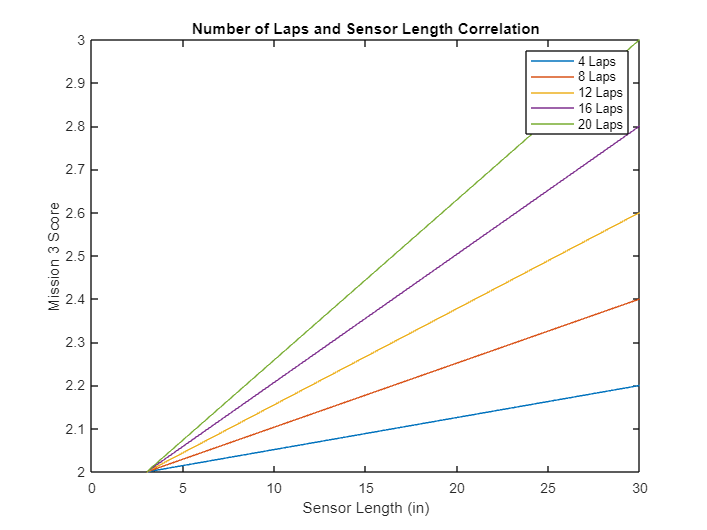

% Defining sensor length vector for the team
team.Array.SensorLength = [linspace(3,bestTeam.SensorLength,50)]';

% Univariate SA for Mission 3 score with the number of laps and sensor length variation
score.Array.M3.Laps2Length = 2 + (team.Array.Laps.*team.SensorWeight.*team.Array.SensorLength)./(bestTeam.Laps*bestTeam.SensorWeight*bestTeam.SensorLength);
plots.Y4.Value = score.Array.M3.Laps2Weight;
plots.Y4.Name = {'4 Laps','8 Laps','12 Laps','16 Laps','20 Laps'};

% Plotting sensitivity analysis plot
figure()
plot(team.Array.SensorLength, plots.Y4.Value)
legend(plots.Y4.Name)
xlabel('Sensor Length (in)')
ylabel('Mission 3 Score')
title('Number of Laps and Sensor Length Correlation')

It can be inferred from the above plot that a longer sensor will be more sensitive to flight time and demand a faster aircraft for a higher score. It is expected as a larger sensor will indirectly lead to heavy aircraft.

#### 1.3.3    Sensor Length and Sensor Weight Correlation

Keeping the number of laps constant, sensor length and sensor height sensitivity can be studied in detail. Here, for this purpose, MATLAB 3D plots provide a particularly good representation. 

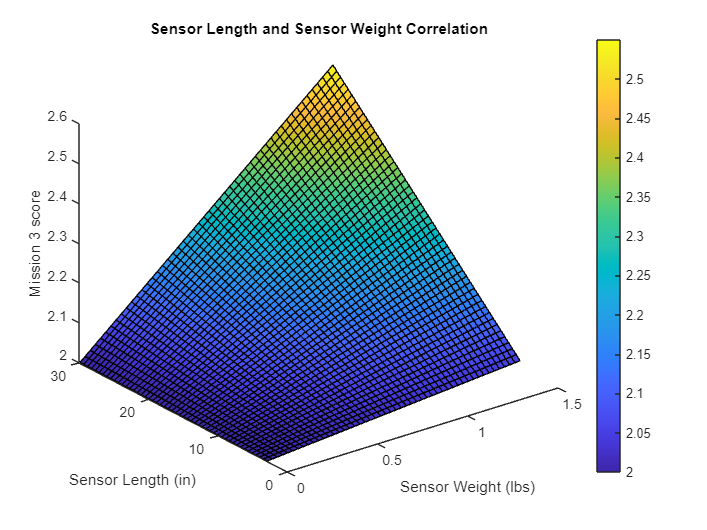

% Selecting the number of laps as constant
team.LapsSelected = 11;

% Preparing mesh grid for 3D plot
[X,Y] = meshgrid(team.Array.SensorWeight, team.Array.SensorLength);
score.Array.M3.Length2Weight = 2 + (team.LapsSelected.*X.*Y)./(bestTeam.Laps*bestTeam.SensorWeight*bestTeam.SensorLength);
plots.Y5.Value = score.Array.M3.Length2Weight;

% Plotting 3D mesh plot for sensitivity analysis
figure()
surface(X,Y,score.Array.M3.Length2Weight)

view(3)
xlabel('Sensor Weight (lbs)')
ylabel('Sensor Length (in)')
zlabel('Mission 3 score')
title('Sensor Length and Sensor Weight Correlation')
colorbar
title('Sensor Length and Sensor Weight Correlation')

The above 3D plot shows, compared to sensor length, sensor weight is more sensitive. Hence a heavy aircraft with a smaller sensor size would be a better choice  than a lighter but longer sensor.

## Summary

From the above scoring sensitivity analysis, it can be inferred that:

- Mission 3 is the most sensitive mission with three design parameters.

- Among all parameters the number of sensors and sensor weight are the most sensitive parameters followed by sensor length, flight time, and the number of laps.

- A heavier and slower aircraft would be a better choice compared to a lighter and faster aircraft.

- Heavier but smaller sensors will be a better choice compared to a lighter but longer sensor.

In the current blog, we learned about sensitivity analysis using the MATLAB plotting approach. We explored design space to evaluate the order of sensitivity of all variables and learned how various design choices can make an impact on mission scores.

In case of any query related to this blog, please feel free to reach out to us at racinglounge@mathworks.com.